# Exercise 6: Quantize the network using calibration data

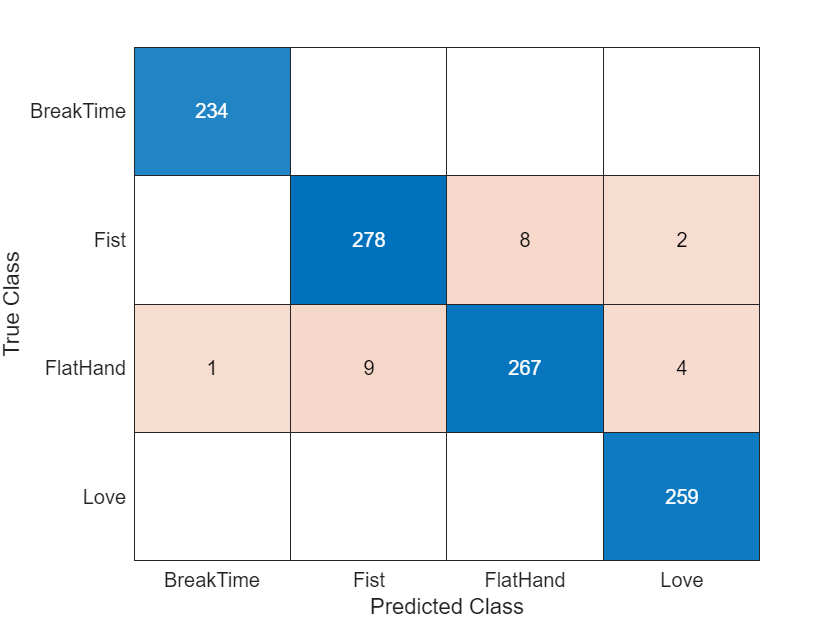

%% Quantize the pretrained network
qLocal = dlquantizer(net, ExecutionEnvironment="MATLAB");
calResults = calibrate(qLocal, xTrain); %#ok<NASGU>
qNet = qLocal.quantize(); 

%% test the Quantized network
scoresQuantized = minibatchpredict(qNet,xTest);
YQuantized = onehotdecode(scoresQuantized,classNames,2);
confusionchart(label_Test,YQuantized);

accuracyQuantized = mean(YQuantized == label_Test); 


%% Export
% will encounter warning
exportONNXQuantizedNetwork(qNet, "net_Quantized.onnx"); 

Start exporting Quantized Network to ONNX


## Try in Dev Cloud

web("https://stm32ai-cs.st.com/home"); 
